# Sync the data between IMU and MC system

## Purpose of file

- Sync the time between the IMU measurements and the MC measurements, that is, estimate the time-shift. 

- FInd the coarse and fine rotation between the twos.

- The time shift is estimated by estimating the angular velocities from the rotation matrices from the MC systems and compare with the angular velocities by the gyroscopes. If they are not aligned, one should compare the norm of the angular velocities, but the coarse alignment was sufficient to get the rotation around the x-axis. The the x component is only compared. Then time shift IMU x-component of omega and sum the squared differences. 

- A fine alignment is also performed by comparing the direction of gravity. This is not so important since this misalignment will be incorporated into the $R$ matrix in the filter. We will not compare rotation matrices only positions.

## Load Data


% Estimate bias from stationary phase.
% FIG_SIZE = [0,0,800*1.5,500*1.5]

normalize_norm_v = @(x) x ./ norm_time(x);


### Load MC data

serie = 2;
exp = 3;

% Load MC data 
% Load MC data 
pathScript = fileparts(matlab.desktop.editor.getActiveFilename)

pathScript = '/home/hakcar/phd/Array-INS-2/code/experiments/liu/serie-2/exp3'



file_mc  =sprintf("imu-%d-000%d.mat", serie, exp);
load(fullfile(pathScript,"raw_data","mc",file_mc));

% Load the data 
newStr = sprintf("imu_%d_000%d", serie, exp);
data_mc = eval(newStr);

### Load IMU data

data_IMU = load(fullfile(pathScript,"raw_data","imu","data_same_frame.mat"));

## Prepare data

N_sens = size(data_IMU.inertial_data_double_rot,1)

N_sens = 192

inds_tot = reshape(1:N_sens,6,[]);
N_imu = size(inds_tot,2);
inds_acc = reshape(inds_tot(1:3,:),[],1);
inds_gyro = reshape(inds_tot(4:6,:),[],1);
data_IMU.gyro = deg2rad(data_IMU.inertial_data_double_rot(inds_gyro,:));
data_IMU.acc = data_IMU.inertial_data_double_rot(inds_acc,:);
data_IMU.time = data_IMU.time_stamp_corr - data_IMU.time_stamp_corr(1);
data_IMU.acc

ans =    -0.3879   -0.4214   -0.4357   -0.4357   -0.3974   -0.3974   -0.4262   -0.3639   -0.3831   -0.4501   -0.4405   -0.3591   -0.3256   -0.4166   -0.4262   -0.4214   -0.3831   -0.4214   -0.4166   -0.3974   -0.4166   -0.3735   -0.4166   -0.3783   -0.3783   -0.3735   -0.3687   -0.4022   -0.4070   -0.4214   -0.3639   -0.3735   -0.4118   -0.3926   -0.3496   -0.4262   -0.4022   -0.3639   -0.4788   -0.3735   -0.3687   -0.3735   -0.4453   -0.4405   -0.3783   -0.4357   -0.4262   -0.4501   -0.3496   -0.3831
   -0.1676   -0.1963   -0.1293   -0.1676   -0.2059   -0.0910   -0.1867   -0.1820   -0.1580   -0.1676   -0.1772   -0.1532   -0.1867   -0.1149   -0.2251   -0.1437   -0.1676   -0.1724   -0.1437   -0.1437   -0.1628   -0.1963   -0.1724   -0.1484   -0.1772   -0.1724   -0.2059   -0.1197   -0.1293   -0.2107   -0.1628   -0.1628   -0.2059   -0.1915   -0.1341   -0.1484   -0.1676   -0.1389   -0.1676   -0.1772   -0.1341   -0.1676   -0.1915   -0.1245   -0.1915   -0.1915   -0.1437   -0.2298   -0.1484   

R_imu2rig_coarse = [ 
    0   -1  0;
    -1  0  0;
    0  0 -1];

data_IMU_mc_frame = struct;
R_imu2rig_coarse

R_imu2rig_coarse =      0    -1     0
    -1     0     0
     0     0    -1


% First around z, then around y, then around x
eul2rotm(deg2rad([-90 0 180]))

ans =     0.0000   -1.0000   -0.0000
   -1.0000   -0.0000   -0.0000
         0    0.0000   -1.0000


R_imu2rig_coarse - eul2rotm(deg2rad([-90 0 180]))

ans = 	1.0e+-15 *

   -0.0612         0    0.1225
         0    0.0612    0.0000
         0   -0.1225         0


data_IMU_mc_frame.r0 = R_imu2rig_coarse*data_IMU.r0

data_IMU_mc_frame = struct with fields:
    r0: [3×32 double]


data_IMU.r0*1e3

ans =    -9.4500   -9.4500   -9.4500   -9.4500   -9.4500   -9.4500   -9.4500   -9.4500   -3.1500   -3.1500   -3.1500   -3.1500   -3.1500   -3.1500   -3.1500   -3.1500    3.1500    3.1500    3.1500    3.1500    3.1500    3.1500    3.1500    3.1500    9.4500    9.4500    9.4500    9.4500    9.4500    9.4500    9.4500    9.4500
    3.1500    3.1500    9.4500    9.4500   -9.4500   -9.4500   -3.1500   -3.1500    3.1500    3.1500    9.4500    9.4500   -9.4500   -9.4500   -3.1500   -3.1500    3.1500    3.1500    9.4500    9.4500   -9.4500   -9.4500   -3.1500   -3.1500    3.1500    3.1500    9.4500    9.4500   -9.4500   -9.4500   -3.1500   -3.1500
    1.0000   -1.0000    1.0000   -1.0000    1.0000   -1.0000    1.0000   -1.0000    1.0000   -1.0000    1.0000   -1.0000    1.0000   -1.0000    1.0000   -1.0000    1.0000   -1.0000    1.0000   -1.0000    1.0000   -1.0000    1.0000   -1.0000    1.0000   -1.0000    1.0000   -1.0000    1.0000   -1.0000    1.0000   -1.0000


data_IMU_mc_frame.r0*1e3

ans =    -3.1500   -3.1500   -9.4500   -9.4500    9.4500    9.4500    3.1500    3.1500   -3.1500   -3.1500   -9.4500   -9.4500    9.4500    9.4500    3.1500    3.1500   -3.1500   -3.1500   -9.4500   -9.4500    9.4500    9.4500    3.1500    3.1500   -3.1500   -3.1500   -9.4500   -9.4500    9.4500    9.4500    3.1500    3.1500
    9.4500    9.4500    9.4500    9.4500    9.4500    9.4500    9.4500    9.4500    3.1500    3.1500    3.1500    3.1500    3.1500    3.1500    3.1500    3.1500   -3.1500   -3.1500   -3.1500   -3.1500   -3.1500   -3.1500   -3.1500   -3.1500   -9.4500   -9.4500   -9.4500   -9.4500   -9.4500   -9.4500   -9.4500   -9.4500
   -1.0000    1.0000   -1.0000    1.0000   -1.0000    1.0000   -1.0000    1.0000   -1.0000    1.0000   -1.0000    1.0000   -1.0000    1.0000   -1.0000    1.0000   -1.0000    1.0000   -1.0000    1.0000   -1.0000    1.0000   -1.0000    1.0000   -1.0000    1.0000   -1.0000    1.0000   -1.0000    1.0000   -1.0000    1.0000


R_imu2rig_coarse_tot = kron(eye(N_imu), R_imu2rig_coarse);
data_IMU_mc_frame.acc = R_imu2rig_coarse_tot*data_IMU.acc;
data_IMU_mc_frame.gyro = R_imu2rig_coarse_tot*data_IMU.gyro;
data_IMU_mc_frame.time = data_IMU.time;
data_IMU_mc_frame.Ts = data_IMU.Ts;
data_IMU_mc_frame.Fs = data_IMU.Fs;
data_IMU_mc_frame.mean_gyro = triad_mean(data_IMU_mc_frame.gyro);
data_IMU_mc_frame.mean_acc = triad_mean(data_IMU_mc_frame.acc);
% assert(all(data_R0_t_shift.R_imu2rig_coarse == eul2rotm(deg2rad([-90 0 180])), "all"))

#### Check MC Data

There are some missing samples in the MC data

p_mm = squeeze(data_mc.RigidBodies.Positions); % Positions in mm

bad_points = logical(any(isnan(p_mm)));
good_points = ~bad_points;

p_tot = p_mm/1000;
p = p_tot(:,good_points);
t_tot = ((data_mc.StartFrame:data_mc.Frames) - 1)/data_mc.FrameRate;
t = t_tot(good_points);


## Check Time 

#### Missing samples in the MC system

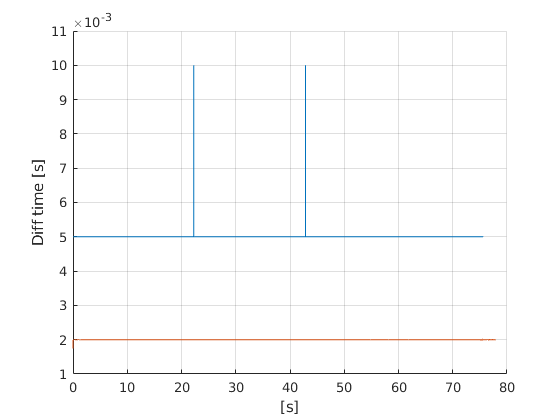

figure(); hold on
plot(t(1:end-1), diff(t), 'DisplayName',"Motion Capture")
plot(data_IMU.time(1:end-1),diff(data_IMU.time),'DisplayName',"IMU")
xlabel("[s]")
ylabel("Diff time [s]")
grid on

Some missing samples.

#### 3D plot of trajectory MC system

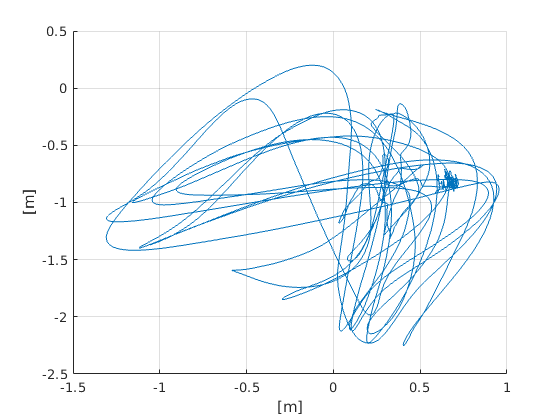

figure(); clf; hold on
plot3(p(1,:),p(2,:), p(3,:))

grid on

xlabel("[m]")
ylabel("[m]")

### Check position in regular 2D plot

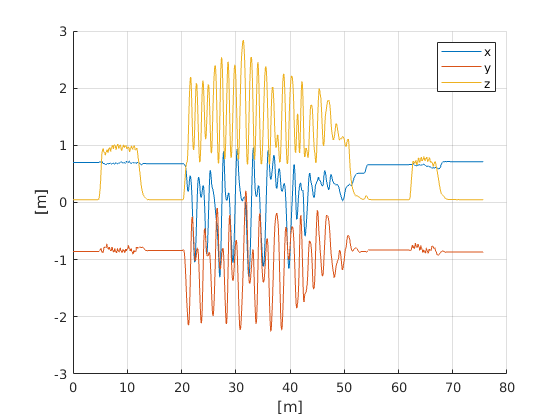

dirs = ["x","y","z"];
figure(); clf; hold on
for i =1:3
    plot(t, p(i,:),"DisplayName",dirs(i))
end

grid on
legend()
xlabel("[m]")
ylabel("[m]")

#### Rig rotation matrix

The rotation matrix is from local to global, that is body to global 

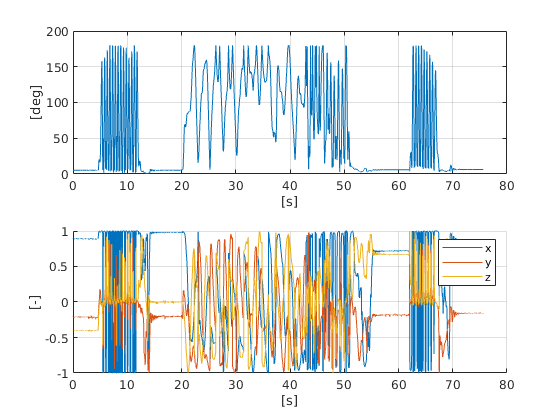

R_nb_rig_tot = squeeze(data_mc.RigidBodies.Rotations); % Rotation matrix
R_nb_rig = R_nb_rig_tot(:,good_points); % Take away nans 
R_nb_rig_3x3 = reshape(R_nb_rig,3,3,[]);
R_bn_rig_3x3 = zeros(size(R_nb_rig_3x3));

for n = 1:size(R_nb_rig_3x3,3)
    R_bn_rig_3x3(:,:,n) = R_nb_rig_3x3(:,:,n)';
end

figure(); hold on
ax = zeros(2,1);

axang = rotm2axang(R_nb_rig_3x3);
ax(1) = subplot(2,1,1);


plot(t, rad2deg(axang(:,4)))
% set(gca, "YScale", "log")
grid on
xlabel("[s]")
ylabel("[deg]")


ax(2) = subplot(2,1,2); hold on
for i = 1:3
    plot(t, axang(:,i))
end
grid on
legend("x","y","z")
xlabel("[s]")
ylabel("[-]")


% linkaxes(ax, "x");

## Estimate angular velocity from MC rotation matrices 

Use a forward differencing scheme.

w_nb_hat =  R2w_central_diff(R_nb_rig_3x3, t)

w_nb_hat =        NaN   -0.0321   -0.0122    0.0142   -0.0123    0.0061    0.0027   -0.0046    0.0381    0.0006   -0.0634   -0.0340    0.0236    0.0472    0.0661    0.0340   -0.0102   -0.0727   -0.0415    0.0237   -0.0525   -0.0417    0.1012    0.0386   -0.0794    0.0550    0.0181   -0.0596   -0.0223   -0.0156    0.0975    0.0464   -0.0275   -0.0550   -0.0322   -0.0021   -0.0207    0.0731   -0.0061   -0.0846   -0.0354    0.0351   -0.0042   -0.0560    0.0919    0.0323   -0.0084    0.0136   -0.0256    0.0309
       NaN   -0.0186   -0.0124   -0.0320    0.0203   -0.0612   -0.0315    0.0722    0.0096   -0.0042   -0.0145    0.0041   -0.0009   -0.0063    0.0057   -0.0020   -0.0058   -0.0054    0.0187    0.0288   -0.0201   -0.0314    0.0159    0.0005    0.0066    0.0123   -0.0193   -0.0022    0.0064    0.0111    0.0083   -0.0102    0.0187   -0.0056   -0.0287    0.0084    0.0126   -0.0177    0.0005    0.0017    0.0024    0.0138   -0.0174    0.0048    0.0028    0.0106    0.0173   -0.0106   -0.02

% Set the neighbours
w_nb_hat(:,1) = w_nb_hat(:,2);
w_nb_hat(:,end) = w_nb_hat(:,end-1);
% zeros(3,length(t));
% 
% for k = 2:length(t)
%     dt = t(k) - t(k-1);
%     w_nb_hat(:,k) = logSO3(R_nb_rig_3x3(:,:,k-1)'*R_nb_rig_3x3(:,:,k))/dt;
% end


## Rotate IMU to IMU-rig coarse

Found this matrix by looking at the photos.

### Plot angular velocity components

figure()
ax = zeros(3,1);
for i = 1:3
    ax(i) = subplot(3,1,i); hold on
    plot(t, w_nb_hat(i,:), "DisplayName","Rig")
    plot(data_IMU_mc_frame.time, data_IMU_mc_frame.mean_gyro(i,:), "DisplayName","IMU")
    grid on 
    legend
end
linkaxes(ax, 'x'); clf reset;

Looks like they are the same.

### Plot angular velocity norm

Compare the norm instead, not depedent on the orientation of the rig

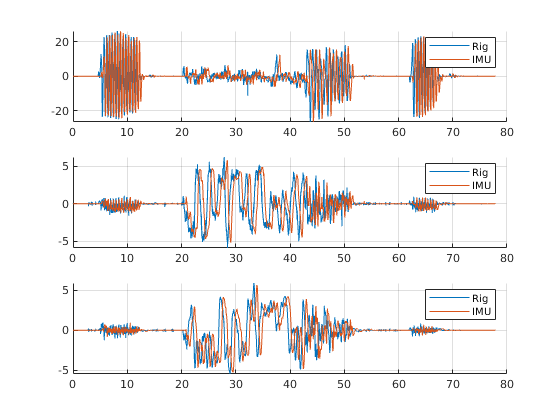

figure()

ax = zeros(3,1);
hold on
plot(t, norm_time(w_nb_hat), "DisplayName","Rig")
plot(data_IMU.time, norm_time(data_IMU_mc_frame.mean_gyro), "DisplayName","IMU")
grid on 
legend

The normed signal of the angular velocity does not look very smooth, that can be explained by the $y$ and $z$ components that are quire noisy. It is then better to just use $x$ component.

## Estimate rotation matrix between IMU and rig using gravity (Fine alignment)

The body frames of the IMU and the rig is not perfectly aligned. 

Downward in bodyframe should point in the direction of gravity in body frame coordinates.

Downward of the navigation frame is the third column of the R_bn matrix, the rotation matrix from navigation frame to body frame.

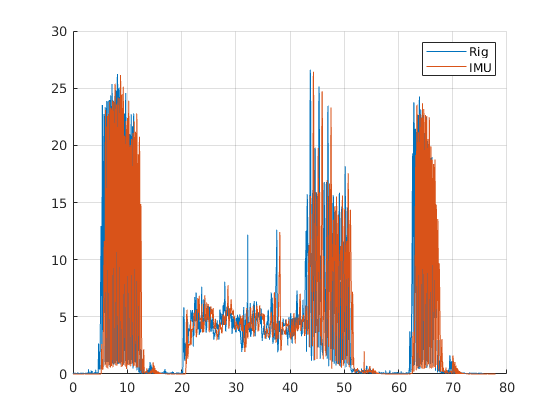

rig_unit_tot = reshape(R_bn_rig_3x3(:,3,:),3,[])
imu_unit_tot = normalize_norm_v(data_IMU_mc_frame.mean_acc)

mask_stationary_rig = t <= 0.5;
mask_stationary_IMU = data_IMU_mc_frame.time <= 4;

figure(); 

rig_unit_tot =     0.0172    0.0174    0.0173    0.0175    0.0177    0.0173    0.0183    0.0176    0.0175    0.0175    0.0176    0.0177    0.0175    0.0177    0.0176    0.0176    0.0176    0.0177    0.0177    0.0175    0.0174    0.0177    0.0177    0.0175    0.0177    0.0175    0.0176    0.0177    0.0176    0.0176    0.0175    0.0175    0.0176    0.0173    0.0176    0.0176    0.0176    0.0175    0.0177    0.0175    0.0177    0.0175    0.0176    0.0177    0.0175    0.0176    0.0174    0.0174    0.0175    0.0177
    0.0814    0.0813    0.0811    0.0812    0.0812    0.0811    0.0813    0.0811    0.0812    0.0815    0.0812    0.0808    0.0809    0.0811    0.0814    0.0817    0.0817    0.0816    0.0810    0.0812    0.0812    0.0807    0.0808    0.0817    0.0812    0.0809    0.0817    0.0811    0.0811    0.0809    0.0810    0.0818    0.0814    0.0816    0.0809    0.0812    0.0809    0.0810    0.0816    0.0810    0.0808    0.0806    0.0811    0.0806    0.0806    0.0815    0.0809    0.0814    

for i = 1:3

imu_unit_tot =     0.0020    0.0018    0.0016    0.0012    0.0021    0.0002    0.0019    0.0013    0.0006    0.0017    0.0001    0.0011    0.0011    0.0002    0.0023    0.0009    0.0012    0.0006   -0.0006    0.0020    0.0012    0.0006    0.0009   -0.0006    0.0015    0.0022    0.0004    0.0002    0.0009    0.0001    0.0010    0.0004    0.0015    0.0020    0.0003    0.0013    0.0012    0.0008    0.0025    0.0004    0.0023    0.0016    0.0003    0.0022    0.0007    0.0013    0.0015    0.0011    0.0004    0.0009
    0.0349    0.0358    0.0353    0.0377    0.0368    0.0362    0.0362    0.0354    0.0363    0.0360    0.0368    0.0353    0.0368    0.0361    0.0362    0.0359    0.0364    0.0355    0.0357    0.0367    0.0361    0.0369    0.0374    0.0353    0.0367    0.0354    0.0366    0.0374    0.0373    0.0364    0.0361    0.0374    0.0369    0.0365    0.0351    0.0371    0.0365    0.0372    0.0377    0.0365    0.0363    0.0370    0.0358    0.0365    0.0353    0.0352    0.0372    0.0348    

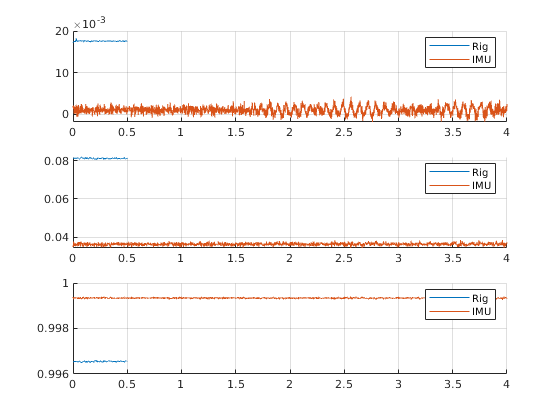

    subplot(3,1,i); hold on 
    plot(t(mask_stationary_rig), rig_unit_tot(i,mask_stationary_rig), "DisplayName","Rig")
    plot(data_IMU.time(mask_stationary_IMU), imu_unit_tot(i,mask_stationary_IMU), "DisplayName","IMU")
    grid on 
    legend
end

### Find angle difference 

[R_stationary_rig_mean, e_R] = average_rotation(R_bn_rig_3x3(:,:,mask_stationary_rig), 100, 1e-12)

1/100: tol: 6.167e-04 / 1.000e-12
2/100: tol: 4.051e-12 / 1.000e-12
3/100: tol: 6.624e-18 / 1.000e-12


R_stationary_rig_mean =     0.9992   -0.0370    0.0176
    0.0355    0.9961    0.0811
   -0.0205   -0.0804    0.9965


e_R = 	1.0e+-3 *

   -0.2774   -0.1808    0.0456   -0.0590   -0.0824    0.0588   -0.1255    0.0405   -0.1060   -0.3486   -0.1091    0.2948    0.2274    0.0572   -0.2419   -0.6079   -0.5849   -0.5026    0.1468   -0.0941   -0.1006    0.4432    0.3298   -0.5793   -0.0583    0.2142   -0.6156    0.0424   -0.0156    0.2603    0.1339   -0.7209   -0.3274   -0.4517    0.2264   -0.1155    0.2447    0.0864   -0.4818    0.1506    0.3666    0.5046    0.0082    0.5522    0.5681   -0.3745    0.2413   -0.2941    0.1081   -0.0268
   -0.3860   -0.1416   -0.2292   -0.0415    0.1047   -0.2391    0.7032    0.0676   -0.0207   -0.0327    0.0248    0.1076   -0.0348    0.1172    0.0460    0.0748    0.0631    0.1357    0.1057   -0.0660   -0.1730    0.1360    0.1361   -0.0085    0.1349   -0.0941    0.0184    0.1126    0.0335    0.0315   -0.0905   -0.0326    0.0238   -0.2254    0.0688    0.0652   -0.0148   -0.0683    0.1794   -0.0639    0.1463   -0.0976    0.0099    0.0737   -0.0496    0.0490   -0.1450   -0.1183 

det(R_stationary_rig_mean)

ans = 1.0000

R_stationary_rig_mean'*R_stationary_rig_mean

ans =     1.0000   -0.0000    0.0000
   -0.0000    1.0000   -0.0000
    0.0000   -0.0000    1.0000


dir_rig = R_stationary_rig_mean(:,3)

dir_rig =     0.0176
    0.0811
    0.9965


norm(dir_rig)

ans = 1.0000

dir_imu = normalize_norm_v(mean(data_IMU_mc_frame.mean_acc(:,mask_stationary_IMU),2))

dir_imu =     0.0010
    0.0364
    0.9993



norm(dir_imu)

ans = 1

acosd(dot(dir_rig,dir_imu))

ans = 2.7397

3 degress difference. Level spirit sensitivity is 10mm/m

atand(10e-3/1)

ans = 0.5729

Which is 0.5 deg. Meaning the difference is above what the level spirit can measure. 

Rotationmatrix between unit vectors, from 

R_rig_coarse2rig_fine = rotationMatrixFromTwoUnitVectors(dir_imu, dir_rig)

R_rig_coarse2rig_fine =     0.9999    0.0002    0.0166
   -0.0009    0.9990    0.0448
   -0.0165   -0.0448    0.9989


It is almost the identiy matrix

rad2deg(my_rotm2eul(R_rig_coarse2rig_fine))

ans =    -2.5706
    0.9475
   -0.0532



det(R_rig_coarse2rig_fine)

ans = 1

R_rig_coarse2rig_fine'*R_rig_coarse2rig_fine

ans =     1.0000   -0.0000         0
   -0.0000    1.0000   -0.0000
         0   -0.0000    1.0000


R_rig_coarse2rig_fine*dir_imu

ans =     0.0176
    0.0811
    0.9965


dir_rig

dir_rig =     0.0176
    0.0811
    0.9965


norm(R_rig_coarse2rig_fine*dir_imu - dir_rig)

ans = 2.4194e-08

How many degress does the rotation matrix rotate.

rad2deg(norm(logSO3(R_rig_coarse2rig_fine)))

ans = 2.7398

Check that the rotation matrix is reasonable 

imu_unit_tot_2 = normalize_norm_v(R_rig_coarse2rig_fine*data_IMU_mc_frame.mean_acc(:,mask_stationary_IMU))

imu_unit_tot_2 =     0.0186    0.0184    0.0181    0.0178    0.0186    0.0168    0.0185    0.0178    0.0172    0.0183    0.0167    0.0177    0.0177    0.0168    0.0188    0.0174    0.0177    0.0171    0.0159    0.0186    0.0178    0.0172    0.0174    0.0160    0.0181    0.0188    0.0170    0.0167    0.0174    0.0167    0.0175    0.0169    0.0181    0.0185    0.0168    0.0178    0.0178    0.0174    0.0190    0.0169    0.0189    0.0182    0.0168    0.0187    0.0173    0.0178    0.0181    0.0177    0.0170    0.0174
    0.0797    0.0806    0.0801    0.0825    0.0816    0.0809    0.0810    0.0802    0.0811    0.0808    0.0816    0.0801    0.0816    0.0809    0.0810    0.0807    0.0812    0.0803    0.0805    0.0815    0.0809    0.0817    0.0822    0.0801    0.0815    0.0801    0.0814    0.0822    0.0821    0.0812    0.0808    0.0822    0.0817    0.0812    0.0799    0.0819    0.0812    0.0820    0.0825    0.0812    0.0811    0.0818    0.0806    0.0813    0.0801    0.0800    0.0819    0.0796  

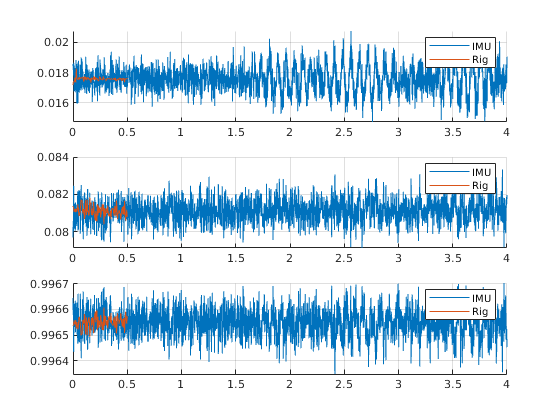

figure(); 
for i = 1:3
    subplot(3,1,i); hold on 
    
    plot(data_IMU.time(mask_stationary_IMU), imu_unit_tot_2(i,mask_stationary_IMU), "DisplayName","IMU")
    plot(t(mask_stationary_rig), rig_unit_tot(i,mask_stationary_rig), "DisplayName","Rig")
    grid on 
    legend
end

Check that gyro gives reasonable reasults as well

phase_roll_1 = data_IMU.start_and_stop(1,2):data_IMU.start_and_stop(2,1);

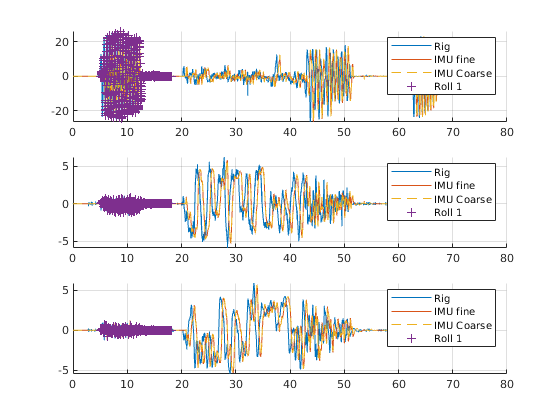

gyro_2 = R_rig_coarse2rig_fine*data_IMU_mc_frame.mean_gyro;
figure()
ax = zeros(3,1);

for i = 1:3
    ax(i) = subplot(3,1,i); hold on
    plot(t, w_nb_hat(i,:), "DisplayName","Rig")
    plot(data_IMU.time, gyro_2(i,:) , "DisplayName","IMU fine ")
    plot(data_IMU.time, data_IMU_mc_frame.mean_gyro(i,:) ,"--", "DisplayName","IMU Coarse")
    plot(data_IMU.time(phase_roll_1), data_IMU_mc_frame.mean_gyro(i,phase_roll_1) ,"+", "DisplayName","Roll 1", "MarkerIndices",1:10:length(phase_roll_1))
    grid on 
    legend
end

The fine rotation does not matter.

#### Rotatate measurements fine alignment

## Grid search time sync

Extract the phase time sync sequence

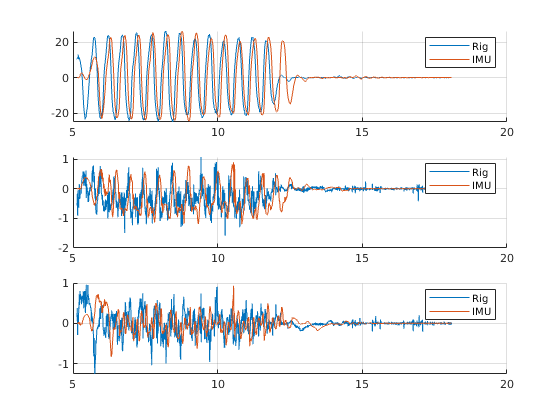


figure
ax = zeros(3,1);
time_IMU = data_IMU.time(phase_roll_1);
mask_time_rig = logical( (t >= time_IMU(1)) .* (t <= time_IMU(end)));
for i = 1:3
    ax(i) = subplot(3,1,i); hold on
    plot(t(mask_time_rig), w_nb_hat(i,mask_time_rig), "DisplayName","Rig")
    plot(time_IMU, data_IMU_mc_frame.mean_gyro(i,phase_roll_1), "DisplayName","IMU")
    grid on 
    legend
end
slice_time_sync_1_phase = phase_roll_1
% linkaxes(ax);

Interpolate rig w to IMU angular velocity. Use the x direction.

y_interp = data_IMU_mc_frame.mean_gyro(1,slice_time_sync_1_phase);

slice_time_sync_1_phase =         2569        2570        2571        2572        2573        2574        2575        2576        2577        2578        2579        2580        2581        2582        2583        2584        2585        2586        2587        2588        2589        2590        2591        2592        2593        2594        2595        2596        2597        2598        2599        2600        2601        2602        2603        2604        2605        2606        2607        2608        2609        2610        2611        2612        2613        2614        2615        2616        2617        2618


t_interp = time_IMU;
length(t_interp)

% cubic spline iterpolation 
f = @(t_shift) interp1( t, w_nb_hat(1,:),  t_interp - t_shift, 'pchip');
f(0)

cost = @(t_shift) sum((y_interp - f(t_shift)).^2);

ans = 6476

cost(0)

Ocular inspection of coarse time shift 

t_shift_coarse = 0


ans =    10.2719   10.3056   10.3367   10.3749   10.4184   10.4842   10.6031   10.7254   10.8276   10.9153   10.9294   10.8780   10.8360   10.9136   11.0708   11.1014   10.9853   10.8904   10.9400   11.0991   11.3984   12.2744   12.9259   12.6052   11.8161   11.1979   10.6499   10.3431   10.7124   11.4827   11.7563   11.8105   11.8330   11.7623   11.5972   11.4783   11.3836   11.3324   11.3687   11.4431   11.4578   11.3926   11.2850   11.1019   10.8304   10.6037   10.4125   10.2474   10.0929    9.9623


grid_search = t_shift_coarse + (-1:0.01:1);
cost_grid = arrayfun(cost, grid_search);


ans = 7.5116e+05

options = optimset('Display','iter','TolX', 1e-12);
t_shift_opt = fminbnd(cost,grid_search(1),grid_search(end),options);


t_shift_coarse = 0

data_IMU.time_shifted = data_IMU.time - t_shift_opt;
figure(); clf;
plot(grid_search, cost_grid, "-x")
hold on 
yLim = ylim;
plot(t_shift_opt*ones(1,2), yLim, "-r")

 
 Func-count     x          f(x)         Procedure
    1      -0.236068  3.20782e+06        initial
    2       0.236068  2.84848e+06        golden
    3       0.527864       256721        golden
    4       0.708204  2.25056e+06        golden
    5        0.48713       929676        parabolic
    6       0.573718      6546.35        parabolic
    7       0.572138      3675.46        parabolic
    8       0.567396      186.298        parabolic
    9       0.567617      177.563        parabolic
   10       0.567622      177.559        parabolic
   11       0.567622      177.559        parabolic
   12       0.567622      177.559        parabolic
   13       0.567622      177.559        parabolic
 
Optimization terminated:
 the current x satisfies the termination criteria using OPTIONS.TolX of 1.000000e-12 



ylim(yLim);

### Ensure time shift is ok

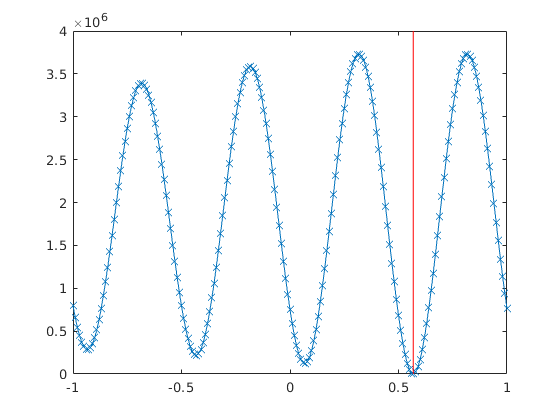

figure(); hold on 

ax = zeros(3,1);
for i = 1:3
    ax(i) = subplot(3,1,i); hold on;
    plot(t, rad2deg(w_nb_hat(i,:))', 'DisplayName', "MC")


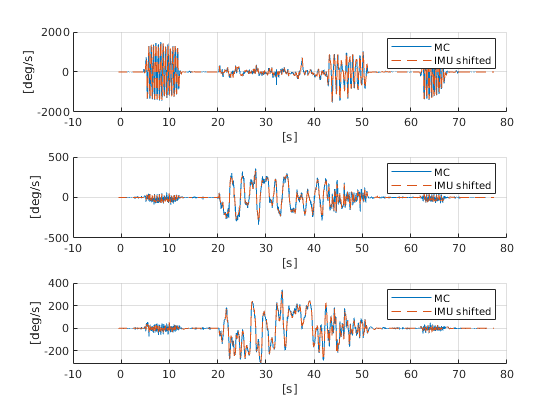

    % plot(data_IMU.time, rad2deg(data_IMU_gyro.gyro_wls_wo_bias_rig_frame_fine(i,:)),'DisplayName','IMU')
    plot(data_IMU.time_shifted, rad2deg(data_IMU_mc_frame.mean_gyro(i,:)),"--",'DisplayName','IMU shifted')
    
    % yLim = ylim; 
    % X = [data_IMU.start_and_stop(1,1) data_IMU.start_and_stop(2,1) data_IMU.start_and_stop(2,1) data_IMU.start_and_stop(1,1)];
    % Y = [yLim(2) yLim(2) yLim(1) yLim(1)];
    % fill(data_IMU.time_stamp_corr(X), Y, "b", "FaceAlpha", 0.2);
    % ylim(yLim);
    grid on 
    legend

    xlabel("[s]")
    ylabel("[deg/s]")
end

figure(); hold on 
plot(data_IMU.time_shifted, "DisplayName","Shifted time")
plot(data_IMU.time, "DisplayName","Original Time")
plot(t, "DisplayName","Rig Time")
legend
grid on 


xlim([0 391])
ylim([-1.35 0.71])

## Find release times

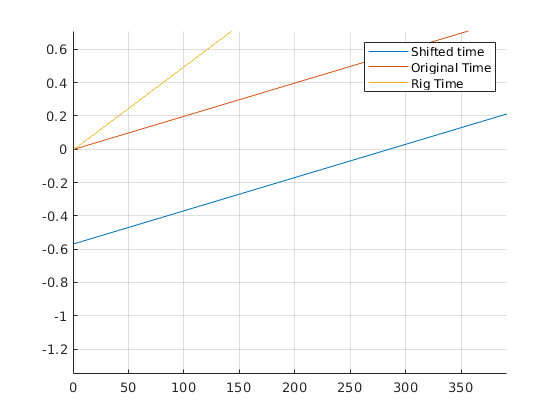



release_times_roll_2 = 62 + (0:19)*0.1
release_times_roll_2_end = release_times_roll_2 + 5;

w_roll_2_start = interp1(data_IMU.time_shifted, data_IMU_mc_frame.mean_gyro', release_times_roll_2)';
w_roll_2_end = interp1(data_IMU.time_shifted, data_IMU_mc_frame.mean_gyro', release_times_roll_2_end)';



release_times_middle = 20 + (0:19)*1.4
release_times_middle_end = release_times_middle + 5;

w_middle_start = interp1(data_IMU.time_shifted, data_IMU_mc_frame.mean_gyro', release_times_middle)';
w_middle_end = interp1(data_IMU.time_shifted, data_IMU_mc_frame.mean_gyro', release_times_middle_end)';

release_times_roll_2 =    62.0000   62.1000   62.2000   62.3000   62.4000   62.5000   62.6000   62.7000   62.8000   62.9000   63.0000   63.1000   63.2000   63.3000   63.4000   63.5000   63.6000   63.7000   63.8000   63.9000



figure(); hold on 

ax = zeros(3,1);
for i = 1:3
    ax(i) = subplot(3,1,i); hold on;


release_times_middle =    20.0000   21.4000   22.8000   24.2000   25.6000   27.0000   28.4000   29.8000   31.2000   32.6000   34.0000   35.4000   36.8000   38.2000   39.6000   41.0000   42.4000   43.8000   45.2000   46.6000


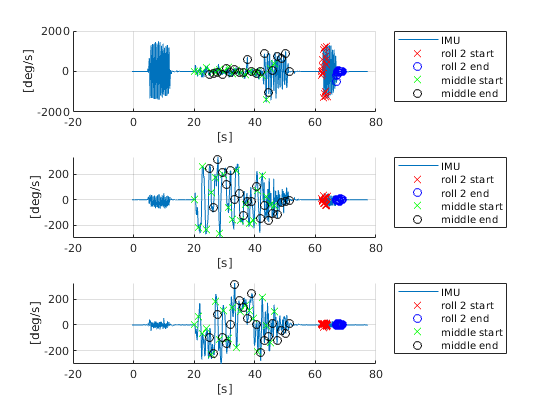

    plot(data_IMU.time_shifted, rad2deg(data_IMU_mc_frame.mean_gyro(i,:)),"-",'DisplayName','IMU')
    plot(release_times_roll_2, rad2deg(w_roll_2_start(i,:)),"rx",'DisplayName','roll 2 start')
    plot(release_times_roll_2_end, rad2deg(w_roll_2_end(i,:)),"bo",'DisplayName','roll 2 end')
    
    plot(release_times_middle, rad2deg(w_middle_start(i,:)),"gx",'DisplayName','middle start')
    plot(release_times_middle_end, rad2deg(w_middle_end(i,:)),"ko",'DisplayName','middle end')

    grid on 
    legend

    xlabel("[s]")
    ylabel("[deg/s]")
    legend("Location","bestoutside")
end

## Save Joint data

mkdir(fullfile(pathScript,"estimated_parameters"))

% save(fullfile(pathScript,"estimated_parameters","R0_and_tshift.mat"), "R_imu2rig_coarse","t_shift_opt");
save(fullfile(pathScript,"estimated_parameters","R0_and_tshift.mat"), "R_imu2rig_coarse","t_shift_opt", "release_times_middle", "release_times_roll_2");
% save(fullfile(pathScript,"data_processed","data_initial_values.mat"),"-struct", "data_initial_values");

## Conclusions 

- Coarse alignment is only off by 3 degrees.

- The time-sync was performed on the fine aligned gyroscope wls data, but it is expected that this does not matter if the time-shift estimation was done on the coarse aligned data.

- The time-shift was estimation was done using linearly interpolated data and grid-search. 